# HW1 Gabe Colangelo

clear
close all
warning off
clc

## Problem 1 Lagrangian Derivation & E.O.M

% Lagrangian Derivation
% x1    = x
% x2    = theta1
% x3    = theta2
% x4    = x_dot
% x5    = theta_dot_1
% x6    = theta_dot_2

syms x(t) x_dot(t) theta1(t) theta_dot_1(t) theta2(t) theta_dot_2(t) M m1 m2...
     L1 L2 x1 x2 x3 x4 x5 x6 g theta1_int theta2_int theta_ddot_1 x_ddot ...
     theta_ddot_2 u s real

% Position vector to cart - inertial coordinates
r_M         = [x;0;0];     

% Rotation Matrix from body frame 1 to inertial frame 
I_DCM_B     = [sin(theta1), cos(theta1), 0;...
               cos(theta1), -sin(theta1),0;...
               0, 0 ,-1];

% Position vector to mass 1, inertial frame: r_m1 = x ix + l br
r_m1        = r_M + I_DCM_B*[L1;0;0];

% Define angle between body frame 1 and body frame 2
beta        = theta2 - theta1;

% Rotation Matrix from body frame 1 to inertial frame 
B_DCM_C     = [cos(beta), -sin(beta), 0;...
               sin(beta), cos(beta), 0;...
               0, 0, 1];

% Position vector to mass 2, inertial frame: r_m2 = x ix + l br + l cr
r_m2        = r_M + I_DCM_B*[L1;0;0] + I_DCM_B*B_DCM_C*[L2;0;0]; 

% Inertial Velocities
v_M        = subs(diff(r_M),diff(x(t),t),x_dot);

v_m1       = simplify(subs(diff(r_m1),[diff(x(t),t), diff(theta1(t),t)]...
             ,[x_dot, theta_dot_1]));

v_m2       = simplify(subs(diff(r_m2),[diff(x(t),t), diff(theta1(t),t)...
             ,diff(theta2(t),t)],[x_dot, theta_dot_1, theta_dot_2]));

% Kinetic Energy
T          = simplify((1/2)*M*transpose(v_M)*v_M + (1/2)*m1*transpose(v_m1)*v_m1...
              + (1/2)*m2*transpose(v_m2)*v_m2);

% Gravitational Forces
W_M        = [0;-M*g;0];
W_m1       = [0;-m1*g;0];
W_m2       = [0;-m2*g;0];

% Differential Displacements
dsM        = subs(diff(r_M),diff(x(t),t),1);
dsm1       = simplify(subs(diff(r_m1),[diff(x(t),t), diff(theta1(t),t)]...
             ,[1 1]));
dsm2        = simplify(subs(diff(r_m2),[diff(x(t),t), diff(theta1(t),t)...
             ,diff(theta2(t),t)],[1 1 1]));

% Potential Energies of mass M: V = -int(dot(F,ds))
V_M        = -int(transpose(W_M)*dsM);

% Potential Energy of mass 1
int_m1     = subs(transpose(W_m1)*dsm1,theta1,theta1_int);
V_m1       = subs(-int(int_m1,theta1_int),theta1_int,theta1);

% Potential Energy of mass 2
int_m2     = subs(transpose(W_m2)*dsm2,[theta1 theta2],[theta1_int, theta2_int]);
V_m2       = subs(-int(subs(int_m2,theta2_int,0),theta1_int) +....
            -int(subs(int_m2,theta1_int,0),theta2_int),[theta1_int,theta2_int],...
              [theta1,theta2]);

% Total potential energy 
V          = simplify(V_M + V_m1 + V_m2);

% Lagrangian
disp('The Lagrangian is')

The Lagrangian is


L          = simplify(T - V)

$$L(t) = \begin{array}{l} \frac{m_{2}\,{\left(\dot{x}\left(t\right)+\sigma_{1}+L_{2}\,\cos\left(\theta_{2}\left(t\right)\right)\,{\dot{\theta }}_{2}\left(t\right)\right)}^{2}}{2}+\frac{m_{1}\,{\left(\dot{x}\left(t\right)+\sigma_{1}\right)}^{2}}{2}+\frac{m_{2}\,{\left(L_{1}\,\sin\left(\theta_{1}\left(t\right)\right)\,{\dot{\theta }}_{1}\left(t\right)+L_{2}\,\sin\left(\theta_{2}\left(t\right)\right)\,{\dot{\theta }}_{2}\left(t\right)\right)}^{2}}{2}+\frac{M\,{\dot{x}\left(t\right)}^{2}}{2}+\frac{{L_{1}}^{2}\,m_{1}\,{\sin\left(\theta_{1}\left(t\right)\right)}^{2}\,{{\dot{\theta }}_{1}\left(t\right)}^{2}}{2}-L_{1}\,g\,m_{1}\,\cos\left(\theta_{1}\left(t\right)\right)-L_{1}\,g\,m_{2}\,\cos\left(\theta_{1}\left(t\right)\right)-L_{2}\,g\,m_{2}\,\cos\left(\theta_{2}\left(t\right)\right)\\ \mathrm{where}\\ \sigma_{1}=L_{1}\,\cos\left(\theta_{1}\left(t\right)\right)\,{\dot{\theta }}_{1}\left(t\right) \end{array}$$

% Lagrange Equations of Motions: d/dt(del_L/del_qdot) - del_L/del_q = Q
disp('Lagranges Equations of Motion are:')

Lagranges Equations of Motion are:


% : q = x, Q = u
eqn_x      = subs(simplify(diff(diff(L,x_dot),t) - diff(L,x)),[diff(x(t),t), diff(theta1(t),t)...
             ,diff(theta2(t),t), diff(x_dot,t), diff(theta_dot_1(t), t), diff(theta_dot_2(t), t)],...
             [x_dot, theta_dot_1, theta_dot_2, x_ddot, theta_ddot_1, theta_ddot_2]) == u

$$eqn\_x(t) = M\,\ddot{x}+m_{1}\,\ddot{x}+m_{2}\,\ddot{x}-L_{1}\,m_{1}\,\sin\left(\theta_{1}\left(t\right)\right)\,{{\dot{\theta }}_{1}\left(t\right)}^{2}-L_{1}\,m_{2}\,\sin\left(\theta_{1}\left(t\right)\right)\,{{\dot{\theta }}_{1}\left(t\right)}^{2}-L_{2}\,m_{2}\,\sin\left(\theta_{2}\left(t\right)\right)\,{{\dot{\theta }}_{2}\left(t\right)}^{2}+L_{1}\,m_{1}\,{\ddot{\theta }}_{1}\,\cos\left(\theta_{1}\left(t\right)\right)+L_{1}\,m_{2}\,{\ddot{\theta }}_{1}\,\cos\left(\theta_{1}\left(t\right)\right)+L_{2}\,m_{2}\,{\ddot{\theta }}_{2}\,\cos\left(\theta_{2}\left(t\right)\right)=u$$

% : q = theta1, Q = 0
eqn_theta1 = subs(simplify(diff(diff(L,theta_dot_1),t) - diff(L,theta1)),[diff(x(t),t), diff(theta1(t),t)...
             ,diff(theta2(t),t), diff(x_dot,t), diff(theta_dot_1(t), t), diff(theta_dot_2(t), t)],...
             [x_dot, theta_dot_1, theta_dot_2, x_ddot, theta_ddot_1, theta_ddot_2]) == 0

$$eqn\_theta1(t) = \begin{array}{l} {L_{1}}^{2}\,m_{1}\,{\ddot{\theta }}_{1}+{L_{1}}^{2}\,m_{2}\,{\ddot{\theta }}_{1}-L_{1}\,g\,m_{1}\,\sin\left(\theta_{1}\left(t\right)\right)-L_{1}\,g\,m_{2}\,\sin\left(\theta_{1}\left(t\right)\right)+L_{1}\,m_{1}\,\ddot{x}\,\cos\left(\theta_{1}\left(t\right)\right)+L_{1}\,m_{2}\,\ddot{x}\,\cos\left(\theta_{1}\left(t\right)\right)+L_{1}\,L_{2}\,m_{2}\,\sin\left(\sigma_{1}\right)\,{{\dot{\theta }}_{2}\left(t\right)}^{2}+L_{1}\,L_{2}\,m_{2}\,{\ddot{\theta }}_{2}\,\cos\left(\sigma_{1}\right)=0\\ \mathrm{where}\\ \sigma_{1}=\theta_{1}\left(t\right)-\theta_{2}\left(t\right) \end{array}$$

% : q = theta2, Q = 0
eqn_theta2 = subs(simplify(diff(diff(L,theta_dot_2),t) - diff(L,theta2)),[diff(x(t),t), diff(theta1(t),t)...
             ,diff(theta2(t),t), diff(x_dot,t), diff(theta_dot_1(t), t), diff(theta_dot_2(t), t)],...
             [x_dot, theta_dot_1, theta_dot_2, x_ddot, theta_ddot_1, theta_ddot_2]) == 0

$$eqn\_theta2(t) = {L_{2}}^{2}\,m_{2}\,{\ddot{\theta }}_{2}-L_{2}\,g\,m_{2}\,\sin\left(\theta_{2}\left(t\right)\right)+L_{2}\,m_{2}\,\ddot{x}\,\cos\left(\theta_{2}\left(t\right)\right)-L_{1}\,L_{2}\,m_{2}\,\sin\left(\theta_{1}\left(t\right)-\theta_{2}\left(t\right)\right)\,{{\dot{\theta }}_{1}\left(t\right)}^{2}+L_{1}\,L_{2}\,m_{2}\,{\ddot{\theta }}_{1}\,\cos\left(\theta_{1}\left(t\right)-\theta_{2}\left(t\right)\right)=0$$

% Solve system of equations for 2nd derivative of states
sys_eqn    = solve([eqn_x,eqn_theta1,eqn_theta2],[x_ddot,theta_ddot_1,theta_ddot_2]);

% Lagrange Equation of motion, state space form
fprintf('\n')
disp('Lagranges Equation of motion in state space form are given by')

Lagranges Equation of motion in state space form are given by


x1_dot      = x4

$$x1\_dot = x_{4}$$

x2_dot      = x5

$$x2\_dot = x_{5}$$

x3_dot      = x6

$$x3\_dot = x_{6}$$

x4_dot      = subs(simplify(sys_eqn.x_ddot),[x theta1 theta2 x_dot theta_dot_1 theta_dot_2],[x1 x2 x3 x4 x5 x6])

$$x4\_dot = \begin{array}{l} \frac{2\,m_{1}\,u+m_{2}\,u-m_{2}\,u\,\sigma_{1}-g\,{m_{1}}^{2}\,\sin\left(2\,x_{2}\right)+2\,L_{1}\,{m_{1}}^{2}\,{x_{5}}^{2}\,\sin\left(x_{2}\right)-g\,m_{1}\,m_{2}\,\sin\left(2\,x_{2}\right)+2\,L_{1}\,m_{1}\,m_{2}\,{x_{5}}^{2}\,\sin\left(x_{2}\right)+L_{2}\,m_{1}\,m_{2}\,{x_{6}}^{2}\,\sin\left(x_{3}\right)+L_{2}\,m_{1}\,m_{2}\,{x_{6}}^{2}\,\sin\left(2\,x_{2}-x_{3}\right)}{2\,M\,m_{1}+M\,m_{2}+m_{1}\,m_{2}-{m_{1}}^{2}\,\cos\left(2\,x_{2}\right)+{m_{1}}^{2}-m_{1}\,m_{2}\,\cos\left(2\,x_{2}\right)-M\,m_{2}\,\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=\cos\left(2\,x_{2}-2\,x_{3}\right) \end{array}$$

x5_dot      = subs(simplify(sys_eqn.theta_ddot_1),[x theta1 theta2 x_dot theta_dot_1 theta_dot_2],[x1 x2 x3 x4 x5 x6])

$$x5\_dot = \begin{array}{l} -\frac{m_{1}\,u\,\cos\left(x_{2}\right)+\frac{m_{2}\,u\,\cos\left(x_{2}\right)}{2}-\frac{m_{2}\,u\,\cos\left(x_{2}-2\,x_{3}\right)}{2}-g\,{m_{1}}^{2}\,\sin\left(x_{2}\right)-M\,g\,m_{1}\,\sin\left(x_{2}\right)-\frac{M\,g\,m_{2}\,\sin\left(x_{2}\right)}{2}-g\,m_{1}\,m_{2}\,\sin\left(x_{2}\right)+\frac{L_{1}\,{m_{1}}^{2}\,{x_{5}}^{2}\,\sin\left(2\,x_{2}\right)}{2}-\frac{M\,g\,m_{2}\,\sin\left(x_{2}-2\,x_{3}\right)}{2}+\frac{L_{2}\,m_{1}\,m_{2}\,{x_{6}}^{2}\,\sin\left(x_{2}+x_{3}\right)}{2}+L_{2}\,M\,m_{2}\,{x_{6}}^{2}\,\sin\left(x_{2}-x_{3}\right)+\frac{L_{2}\,m_{1}\,m_{2}\,{x_{6}}^{2}\,\sin\left(x_{2}-x_{3}\right)}{2}+\frac{L_{1}\,m_{1}\,m_{2}\,{x_{5}}^{2}\,\sin\left(2\,x_{2}\right)}{2}+\frac{L_{1}\,M\,m_{2}\,{x_{5}}^{2}\,\sin\left(\sigma_{1}\right)}{2}}{L_{1}\,\left(M\,m_{1}+\frac{M\,m_{2}}{2}+\frac{m_{1}\,m_{2}}{2}-\frac{{m_{1}}^{2}\,\cos\left(2\,x_{2}\right)}{2}+\frac{{m_{1}}^{2}}{2}-\frac{m_{1}\,m_{2}\,\cos\left(2\,x_{2}\right)}{2}-\frac{M\,m_{2}\,\cos\left(\sigma_{1}\right)}{2}\right)}\\ \mathrm{where}\\ \sigma_{1}=2\,x_{2}-2\,x_{3} \end{array}$$

x6_dot      = subs(simplify(sys_eqn.theta_ddot_2),[x theta1 theta2 x_dot theta_dot_1 theta_dot_2],[x1 x2 x3 x4 x5 x6])

$$x6\_dot = \begin{array}{l} \frac{\frac{m_{1}\,u\,\sigma_{2}}{2}-\frac{m_{2}\,u\,\cos\left(x_{3}\right)}{2}-\frac{m_{1}\,u\,\cos\left(x_{3}\right)}{2}+\frac{m_{2}\,u\,\sigma_{2}}{2}-\frac{M\,g\,m_{1}\,\sigma_{1}}{2}-\frac{M\,g\,m_{2}\,\sigma_{1}}{2}+\frac{M\,g\,m_{1}\,\sin\left(x_{3}\right)}{2}+\frac{M\,g\,m_{2}\,\sin\left(x_{3}\right)}{2}+L_{1}\,M\,m_{1}\,{x_{5}}^{2}\,\sin\left(x_{2}-x_{3}\right)+L_{1}\,M\,m_{2}\,{x_{5}}^{2}\,\sin\left(x_{2}-x_{3}\right)+\frac{L_{2}\,M\,m_{2}\,{x_{6}}^{2}\,\sin\left(\sigma_{3}\right)}{2}}{L_{2}\,\left(M\,m_{1}+\frac{M\,m_{2}}{2}+\frac{m_{1}\,m_{2}}{2}-\frac{{m_{1}}^{2}\,\cos\left(2\,x_{2}\right)}{2}+\frac{{m_{1}}^{2}}{2}-\frac{m_{1}\,m_{2}\,\cos\left(2\,x_{2}\right)}{2}-\frac{M\,m_{2}\,\cos\left(\sigma_{3}\right)}{2}\right)}\\ \mathrm{where}\\ \sigma_{1}=\sin\left(2\,x_{2}-x_{3}\right)\\ \sigma_{2}=\cos\left(2\,x_{2}-x_{3}\right)\\ \sigma_{3}=2\,x_{2}-2\,x_{3} \end{array}$$

## Part 2 Linearized Model Derivation

% Numerical Parameters
m1_num      = 0.5;
L1_num      = 0.5;
m2_num      = 0.75;
L2_num      = 0.75;
M_num       = 1.5;
g_num       = 9.81;

% Define Non-linear system
f           = [x1_dot;x2_dot;x3_dot;x4_dot;x5_dot;x6_dot];
h           = [x1;x2;x3];

% Jacobian Matrices
df_dx       = jacobian(f,[x1;x2;x3;x4;x5;x6]);
df_du       = jacobian(f,u);
dh_dx       = jacobian(h,[x1;x2;x3;x4;x5;x6]);
dh_du       = jacobian(h,u);

% Equilibirum pair - origin
xe          = zeros(6,1);
ue          = 0;

fprintf('\n')
disp('The linearized state space model about the origin is')

The linearized state space model about the origin is


% Linearized Model
A           = double(subs(df_dx,[x1;x2;x3;x4;x5;x6;ue;m1;L1;m2;L2;M;g],[xe;ue;m1_num;L1_num;m2_num;L2_num;M_num;g_num]))

A =          0         0         0    1.0000         0         0
         0         0         0         0    1.0000         0
         0         0         0         0         0    1.0000
         0   -8.1750         0         0         0         0
         0   65.4000  -29.4300         0         0         0
         0  -32.7000   32.7000         0         0         0


B           = double(subs(df_du,[x1;x2;x3;x4;x5;x6;ue;m1;L1;m2;L2;M;g],[xe;ue;m1_num;L1_num;m2_num;L2_num;M_num;g_num]))

B =          0
         0
         0
    0.6667
   -1.3333
         0


C           = double(dh_dx)

C =      1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0


D           = double(dh_du)

D =      0
     0
     0


## Problem 3 Linearized Model

% Controllability Matrix
Co          = ctrb(A,B);

% Observability Matrix
Ob          = obsv(A,C);

% Number of states
n           = length(A);

% Verify system is reachable & observable
if rank(Co) == n
    disp('Pair (A,B) of the linearized model is reachable/controllable')
end

Pair (A,B) of the linearized model is reachable/controllable



if rank(Ob) == n
    disp('Pair (A,C) of the linearized model is observable')
end

Pair (A,C) of the linearized model is observable


% Inverse of Controllability Matrix
Co_inv      = inv(Co);

% Last row of inverse of Controllability Matrix
q1          = Co_inv(end,:);

% Transformation matrix used to get CCF
T_ccf       = [q1;q1*A;q1*A^2;q1*A^3;q1*A^4;q1*A^5];

% Transform System into Controller Canonical Form
disp('The Linearized Model in Controller Form is')

The Linearized Model in Controller Form is


A_ccf       = T_ccf*A*inv(T_ccf)

A_ccf = 	1.0e+03 *

         0    0.0010         0   -0.0000         0   -0.0000
         0         0    0.0010         0    0.0000         0
         0         0         0    0.0010         0    0.0000
         0         0    0.0000         0    0.0010         0
         0         0         0         0         0    0.0010
         0         0   -1.1762         0    0.0981         0


B_ccf       = T_ccf*B

B_ccf =          0
         0
         0
   -0.0000
         0
    1.0000


C_ccf       = C*inv(T_ccf)

C_ccf =   427.7160         0  -54.5000         0    0.6667         0
         0         0   43.6000         0   -1.3333         0
         0         0   43.6000         0    0.0000         0


D_ccf       = D

D_ccf =      0
     0
     0


% Controllability Matrix of (A',C')
Co_dual     = ctrb(A',C');

% Row reduced echelon form of Controlability, get indice of pivots
[co_ref,p]  = rref(Co_dual);

% Form L martix from inspection - L = [c1',A'*c1', c2',A'*c2', c3', A'*c3']
L_obs       = [C(1,:)', A'*C(1,:)',C(2,:)', A'*C(2,:)',C(3,:)', A'*C(3,:)'];

% Inverse of L 
inv_L       = inv(L_obs);

% Observability Matrices from inspection
d1_obs      = 2;
d2_obs      = 2;
d3_obs      = 2;

% Vectors needed for transformation matrix
q1          = inv_L(d1_obs,:);
q2          = inv_L(d2_obs + d1_obs,:);
q3          = inv_L(d3_obs + d2_obs + d1_obs,:);

% Form Transformation Matrix
T_obs       = [q1; q1*A'; q2; q2*A'; q3; q3*A'];

% Transform linear system into observer form
disp('The Linearized Model in Observer Form is')

The Linearized Model in Observer Form is


A_obs       = (T_obs*A'*inv(T_obs))'

A_obs =          0         0         0   -8.1750         0         0
    1.0000         0         0         0         0         0
         0         0         0   65.4000         0  -29.4300
         0         0    1.0000         0         0         0
         0         0         0  -32.7000         0   32.7000
         0         0         0         0    1.0000         0


C_obs       = (T_obs*C')'

C_obs =      0     1     0     0     0     0
     0     0     0     1     0     0
     0     0     0     0     0     1


B_obs       = (B'*inv(T_obs))'

B_obs =     0.6667
         0
   -1.3333
         0
         0
         0


D_obs       = D

D_obs =      0
     0
     0


## Problem 4 Transfer Function

% Transfer Function Matrix Equation
Y_U         = C*inv(s*eye(size(A)) - A)*B + D;

disp('Transfer function for X to u:')

Transfer function for X to u:


disp(simplify(Y_U(1)))

$$\frac{4\,\left(500\,s^{4}-40875\,s^{2}+320787\right)}{3\,s^{2}\,\left(1000\,s^{4}-98100\,s^{2}+1176219\right)}$$

disp('Transfer Function for theta_1 to u:')

Trasnfer Function for theta_1 to u:


disp(Y_U(2))

$$-\frac{400\,\left(10\,s^{2}-327\right)}{3\,\left(1000\,s^{4}-98100\,s^{2}+1176219\right)}$$

disp('Transfer Function for theta_2 to u:')

Transfer Function for theta_2 to u:


disp(Y_U(3))

$$\frac{43600}{1000\,s^{4}-98100\,s^{2}+1176219}$$

## Problem 5 - Part 1 Pendulum Simulation

% Initial Conditions [m, rad, rad, m/s, rad/s, rad/s]
x0          = [0 .01 .02 0 0 0]';  

% Time interval
dt          = 1/200;

% time and input 
time        = (0:dt:10)';
u           = 0;

% ODE45 Function Call
[~, X] = ode45(@(t,x) DIPC(t,x,u,m1_num,m2_num,M_num,L1_num,L2_num,g_num),time,x0);


## Problem 5 Part - 2 Animation

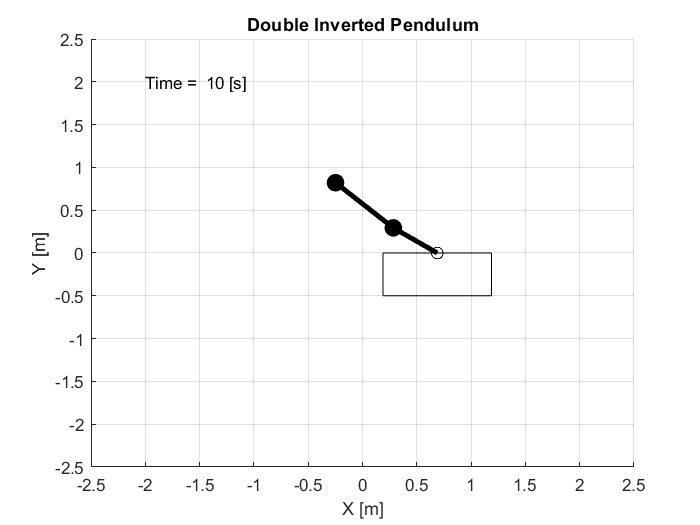

% Cart width and height
w           = 1;
h           = .5;

% Graphics handle - cart
cart        = rectangle('position',[X(1,1) - w/2, -h, w, h]);

% Graphics handle - hinge 
hinge      = line('xdata', X(1,1),'ydata',0,'marker','o','markersize',7);

% Graphics handle - mass 1
mass1       = line('xdata', X(1,1) + L1_num*sin(X(1,2)), 'ydata', L1_num*cos(X(1,2)),...
              'marker','o','markersize',10,'MarkerFaceColor','k');

% Graphics handle - bar 1
bar1        = line('xdata', [X(1,1) X(1,1) + L1_num*sin(X(1,2))],'ydata',...
               [0 L1_num*cos(X(1,2))],'linewidth',3);   

% Graphics handle - mass 2
mass2       = line('xdata', X(1,1) + L1_num*sin(X(1,2)) + L2_num*sin(X(1,3)), 'ydata',...
               L1_num*cos(X(1,2))+L2_num*cos(X(1,3)),'marker','o','markersize',10,'MarkerFaceColor','k');

% Graphics handle - bar 2
bar2        = line('xdata', [(X(1,1) + L1_num*sin(X(1,2))), (X(1,1) + L1_num*sin(X(1,2)) + L2_num*sin(X(1,3)))],'ydata',...
               [(L1_num*cos(X(1,2))) (L1_num*cos(X(1,2))+L2_num*cos(X(1,3)))],'linewidth',3);  

h_txt       = text(-2,2,strcat(['Time = ',' ', num2str(time(1)), ' [s]']));

% Define axis limits
axis([-2*(L1_num + L2_num), 2*(L1_num + L2_num),-2*(L1_num + L2_num), 2*(L1_num + L2_num)]);
grid on
xlabel('X [m]')
ylabel('Y [m]')
title('Double Inverted Pendulum')

% Video stuff
vidobj      = VideoWriter('DIPC.avi');
open(vidobj);
nframes     = length(X);
frames      = moviein(nframes);

for i = 2:nframes

    % Update handles
    set(cart,'position',[X(i,1) - w/2, -h, w, h]);
    set(hinge,'xdata', X(i,1),'ydata',0,'marker','o','markersize',7);
    set(mass1,'xdata', X(i,1) + L1_num*sin(X(i,2)), 'ydata', L1_num*cos(X(i,2)),...
                  'marker','o','markersize',10,'MarkerFaceColor','k');
    set(bar1,'xdata', [X(i,1) X(i,1) + L1_num*sin(X(i,2))],'ydata',...
                   [0 L1_num*cos(X(i,2))],'linewidth',3);   
    set(mass2,'xdata', X(i,1) + L1_num*sin(X(i,2)) + L2_num*sin(X(i,3)), 'ydata',...
                   L1_num*cos(X(i,2))+L2_num*cos(X(i,3)),'marker','o','markersize',10,'MarkerFaceColor','k');
    set(bar2,'xdata', [(X(i,1) + L1_num*sin(X(i,2))), (X(i,1) + L1_num*sin(X(i,2)) + L2_num*sin(X(i,3)))],'ydata',...
                   [(L1_num*cos(X(i,2))) (L1_num*cos(X(i,2))+L2_num*cos(X(i,3)))],'linewidth',3); 
    set(h_txt,'String',strcat(['Time = ',' ', num2str(time(i)), ' [s]']));

    drawnow;
    frames(:,i) = getframe(gcf);
    writeVideo(vidobj,frames(:,i));
end

close(vidobj);

## Function for Double Inverted Cart Pendulum

function xdot = DIPC(t,x,u,m1,m2,M,L1,L2,g)

% States and inputs
x1      = x(1,1); % x
x2      = x(2,1); % theta_1
x3      = x(3,1); % theta_2
x4      = x(4,1); % xdot
x5      = x(5,1); % theta_1_dot
x6      = x(6,1); % theta_2_dot


% Equations of Motion
x1dot   = x4;   % xdot
x2dot   = x5;   % theta_1_dot
x3dot   = x6;   % theta_2_dot

% x_ddot
x4dot   = (2*m1*u + m2*u - m2*u*cos(2*x2 - 2*x3) - g*m1^2*sin(2*x2) +...
          2*L1*m1^2*x5^2*sin(x2) - g*m1*m2*sin(2*x2) +...
          2*L1*m1*m2*x5^2*sin(x2) + L2*m1*m2*x6^2*sin(x3) +...
          L2*m1*m2*x6^2*sin(2*x2 - x3))/(2*M*m1 + M*m2 + m1*m2 -...
          m1^2*cos(2*x2) + m1^2 - m1*m2*cos(2*x2) - M*m2*cos(2*x2 - 2*x3));

% theta_1_ddot
x5dot   = -(m1*u*cos(x2) + (m2*u*cos(x2))/2 - (m2*u*cos(x2 - 2*x3))/2 -...
           g*m1^2*sin(x2) - M*g*m1*sin(x2) - (M*g*m2*sin(x2))/2 -...
           g*m1*m2*sin(x2) + (L1*m1^2*x5^2*sin(2*x2))/2 - (M*g*m2*...
           sin(x2 - 2*x3))/2 + (L2*m1*m2*x6^2*sin(x2 + x3))/2 + ...
           L2*M*m2*x6^2*sin(x2 - x3) + (L2*m1*m2*x6^2*sin(x2 - x3))/2 +...
           (L1*m1*m2*x5^2*sin(2*x2))/2 + (L1*M*m2*x5^2*sin(2*x2 - 2*x3))/2)...
           /(L1*(M*m1 + (M*m2)/2 + (m1*m2)/2 - (m1^2*cos(2*x2))/2 + m1^2/2 ...
           - (m1*m2*cos(2*x2))/2 - (M*m2*cos(2*x2 - 2*x3))/2));

% theta_2_ddot
x6dot   = ((m1*u*cos(2*x2 - x3))/2 - (m2*u*cos(x3))/2 - (m1*u*cos(x3))/2 +...
          (m2*u*cos(2*x2 - x3))/2 - (M*g*m1*sin(2*x2 - x3))/2 - ...
          (M*g*m2*sin(2*x2 - x3))/2 + (M*g*m1*sin(x3))/2 + ...
          (M*g*m2*sin(x3))/2 + L1*M*m1*x5^2*sin(x2 - x3) +...
          L1*M*m2*x5^2*sin(x2 - x3) + (L2*M*m2*x6^2*sin(2*x2 - 2*x3))/2)/...
          (L2*(M*m1 + (M*m2)/2 + (m1*m2)/2 - (m1^2*cos(2*x2))/2 + m1^2/2 -...
          (m1*m2*cos(2*x2))/2 - (M*m2*cos(2*x2 - 2*x3))/2));

xdot    = [x1dot;x2dot;x3dot;x4dot;x5dot;x6dot];

end